Primeri za razdelek štirikotnih Bézierjevih ploskev.

export_images = true; % nastavi na false da se slike ne exportajo

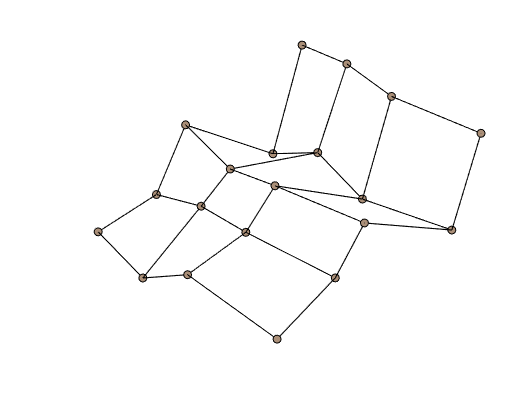

rng(5, 'twister')

Bx = [1 3 4 7 8; 1 3 4 7 8; 1 3 4 7 8; 1 3 4 7 8];
By = [1 1 1 1 1; 3 3 3 3 3; 4 4 4 4 4; 5 5 5 5 5];
Bz = [1 1.2 1.5 1.3 1.8; 1 1.2 1.5 1.3 1.8; 1 1.2 1.5 1.3 1.8; 1 1.2 1.5 1.3 1.8];

Bz = Bz + 0.2*rand(4, 5);

figure
mesh(Bx, By, Bz, 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(Bx, By, Bz, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');

grid off
set(gca,'visible','off')

if export_images
    exportgraphics(gcf, 'b2_example1.pdf', 'ContentType', 'vector')
end

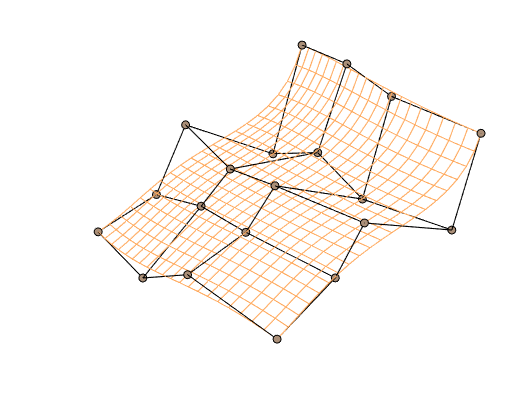

rng(5, 'twister')

Bx = [1 3 4 7 8; 1 3 4 7 8; 1 3 4 7 8; 1 3 4 7 8];
By = [1 1 1 1 1; 3 3 3 3 3; 4 4 4 4 4; 5 5 5 5 5];
Bz = [1 1.2 1.5 1.3 1.8; 1 1.2 1.5 1.3 1.8; 1 1.2 1.5 1.3 1.8; 1 1.2 1.5 1.3 1.8];

Bz = Bz + 0.2*rand(4, 5);

u = linspace(0, 1, 21);

[bx, by, bz] = bezier2(Bx, By, Bz, u, u);

figure
surf(bx, by, bz, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
hold on
mesh(Bx, By, Bz, 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(Bx, By, Bz, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');

grid off
set(gca,'visible','off')

if export_images
    exportgraphics(gcf, 'b2_example2.pdf', 'ContentType', 'vector')
end

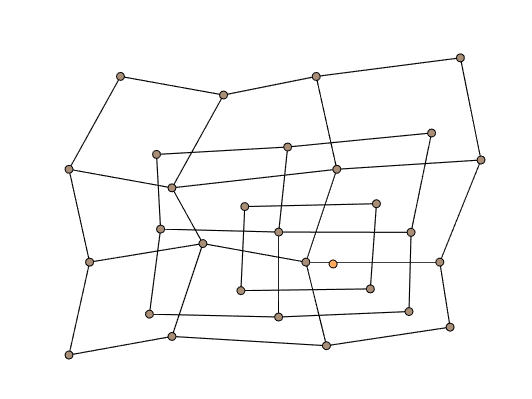

Bx = [1 2 3.5 4.7; 1.2 2.3 3.3 4.6; 1 2 3.6 5; 1.5 2.5 3.4 4.8];
By = [1 1.2 1.1 1.3; 2 2.2 2 2; 3 2.8 3 3.1; 4 3.8 4 4.2];

u = 0.7;
v = 0.3;

figure
mesh(Bx, By, zeros(size(Bx)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter(Bx, By, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on

for i = 1:3
    Bx = (1-u)*Bx(:, 1:end-1) + u*Bx(:, 2:end);
    Bx = (1-v)*Bx(1:end-1, :) + v*Bx(2:end, :);
    By = (1-u)*By(:, 1:end-1) + u*By(:, 2:end);
    By = (1-v)*By(1:end-1, :) + v*By(2:end, :);

    if size(Bx, 1) == 1
        scatter(Bx, By, 'filled', 'MarkerFaceColor', '#FFAA5E', 'MarkerEdgeColor', 'Black');
        hold on
    else
        mesh(Bx, By, zeros(size(Bx)), 'EdgeColor', 'black', 'FaceColor', 'none');
        hold on
        scatter(Bx, By, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
        hold on
    end
end

grid off
set(gca, 'visible', 'off')

view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'b2_geometric.pdf', 'ContentType', 'vector')
end

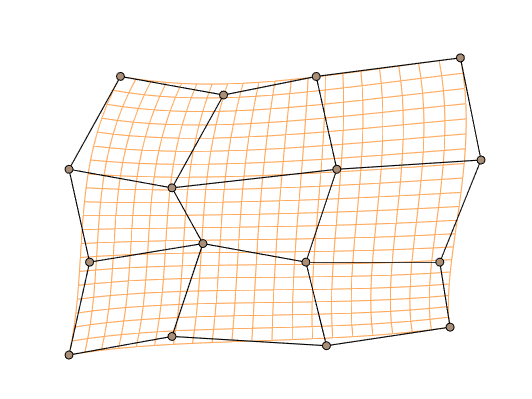

Bx = [1 2 3.5 4.7; 1.2 2.3 3.3 4.6; 1 2 3.6 5; 1.5 2.5 3.4 4.8];
By = [1 1.2 1.1 1.3; 2 2.2 2 2; 3 2.8 3 3.1; 4 3.8 4 4.2];

u = linspace(0, 1, 21);

[bx, by, bz] = bezier2_elevate(Bx, By, zeros(size(Bx)), 4, 2);

[b1, b2, b3] = bezier2(Bx, By, zeros(size(Bx)), u, u);
[c1, c2, c3] = bezier2(bx, by, bz, u, u);

figure
surf(b1, b2, b3, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
hold on
mesh(Bx, By, zeros(size(Bx)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter(Bx, By, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');

grid off
set(gca, 'visible', 'off')

view([-0.50 90.00])
if export_images
    exportgraphics(gcf, 'b2_elevation1.pdf', 'ContentType', 'vector')
end

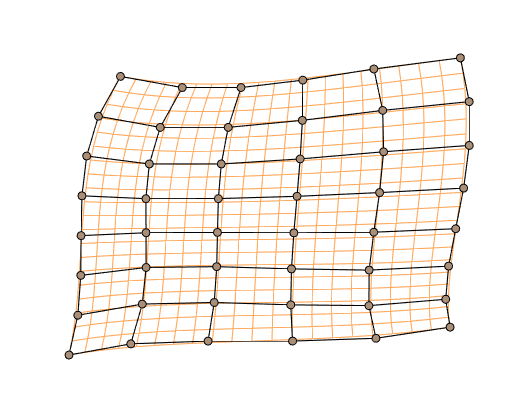


figure
surf(c1, c2, c3, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
hold on
mesh(bx, by, zeros(size(bx)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter(bx, by, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');

grid off
set(gca, 'visible', 'off')

view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'b2_elevation2.pdf', 'ContentType', 'vector')
end

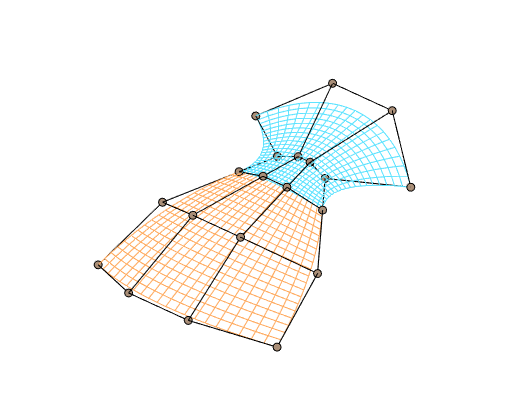

Bx = [1.5 1 1 1.5; 2.4 2 2 2.4; 3.1 3 3 3.1];
By = [1 2 3 4; 1.2 2.1 2.9 3.8; 1.8 2.3 2.7 3.2];
Bz = [1 1.2 1.2 1; 2.5 3 3 2.5; 3.5 3.8 3.8 3.5];

Bx2 = [3.1 3 3 3.1; 3/2 * Bx(3, :) - 1/2 * Bx(2, :); 4 4.5 4.5 4];
By2 = [1.8 2.3 2.7 3.2; 3/2 * By(3, :) - 1/2 * By(2, :); 1.2 2 3 3.8];
Bz2 = [3.5 3.8 3.8 3.5; 3/2 * Bz(3, :) - 1/2 * Bz(2, :); 4.2 5.5 5.5 4.2];

u = linspace(0, 1, 21);

[b1, b2, b3] = bezier2(Bx, By, Bz, u, u);
[c1, c2, c3] = bezier2(Bx2, By2, Bz2, u, u);

figure
surf(b1, b2, b3, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
hold on
surf(c1, c2, c3, 'FaceColor', 'None', 'EdgeColor', '#5EE3FF');
hold on
mesh(Bx, By, Bz, 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(Bx, By, Bz, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
mesh(Bx2, By2, Bz2, 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(Bx2, By2, Bz2, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');

grid off
set(gca, 'visible', 'off')

if export_images
    exportgraphics(gcf, 'b2_spline.pdf', 'ContentType', 'vector')
end

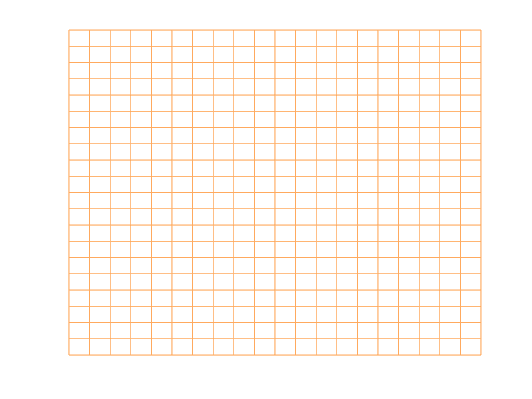

N = 5;
u = linspace(0, 1, 21);

Bx = repmat(1:N, N, 1);
By = Bx';
Bz = zeros(size(Bx));

[bx, by, bz] = bezier2(Bx, By, Bz, u, u);

figure
surf(bx, by, bz, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
grid off
set(gca,'visible','off')

view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'b2_param_domain.pdf', 'ContentType', 'vector')
end

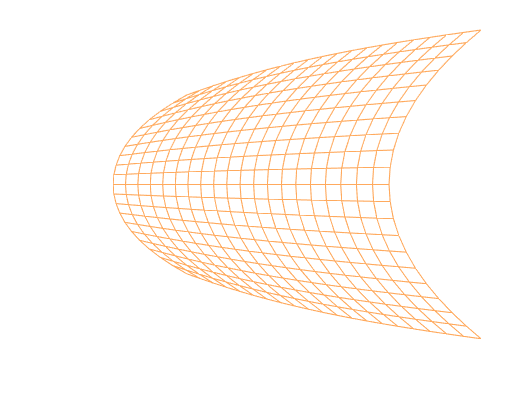

Bx = [4 7 10 14; 2 0 0 12; 1 0 0 10; 1 0 0 10; 2 0 0 12; 4 7 10 14];
By = [5 3 2 1; 7 0 0 4; 9 0 0 8; 12 0 0 13; 14 0 0 17; 16 18 19 20];

[bx, by] = coons_patch(Bx, By);
[bx, by, bz] = bezier2(bx, by, zeros(size(bx)), u, u);

figure
surf(bx, by, bz, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
grid off
set(gca,'visible','off')

view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'b2_real_domain.pdf', 'ContentType', 'vector')
end